# **Controllo di un elicottero (29/01/2021)**

In un elicottero a 2 DOF (gradi di libertà) è possibile ottenere un sistema accoppiato a 2 ingressi e 2 uscite a causa dell'accoppiamento tra i pitch e yaw motor torques. L'elicottero a 2 DOF è rappresentato nello spazio di stato dalle seguenti matrici:


$$A=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & -\frac{B_P }{J_{P\;} +{\textrm{mL}}^2 } & 0\\
0 & 0 & 0 & -\frac{B_Y }{J_Y +{\textrm{mL}}^2 }
\end{array}\right\rbrack ,\;\;\;\;B=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
\frac{K_{\textrm{PP}} }{J_P +{\textrm{mL}}^2 } & \frac{K_{\textrm{PY}} }{J_P +{\textrm{mL}}^2 }\\
\frac{K_{\textrm{YP}} }{J_Y +{\textrm{mL}}^2 } & \frac{K_{\textrm{YY}} }{J_Y +{\textrm{mL}}^2 }
\end{array}\right\rbrack ,\;\;\;\;C=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack ,\;\;\;\;D=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack$$


dove $\theta \;\left(t\right)$ è il pitch angle, $\psi \;\left(t\right)$ è il yaw angle ed $u_P \left(t\right)$ e $u_Y \left(t\right)$ sono, rispettivamente, i segnali di controllo applicati ai pitch e yaw motors.

I diversi parametri caratterizzanti la rappresentazione nello spazio di stato sono riportati nella seguente tabella:

## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Parametri del sistema

% Coppie [Nm/V]
Kpp = 0.2040;
Kyy = 0.0720;
Kpy = 0.0068;
Kyp = 0.0219;

% Momenti di inerzia [kg/m^2]
Jp = 0.0384;
Jy = 0.0432;

% Smorzamento viscoso [NN]
Bp = 0.0800;
By = 0.3180;

% Massa [kg]
m = 1.3872;

% Centro di massa [m]
L = 0.1860;

### Matrici del sistema

% Matrici del sistema linearizzato
A = [0, 0,              1,              0;
     0, 0,              0,              1;
     0, 0, -Bp/(Jp+m*L^2),              0;
     0, 0,              0, -By/(Jy+m*L^2)];

B = [             0,              0;
                  0,              0;
     Kpp/(Jp+m*L^2), Kpy/(Jp+m*L^2);
     Kyp/(Jy+m*L^2), Kyy/(Jy+m*L^2)];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

D = zeros(2,2);

### Definizione del sistema

% Sistema nello spazio di stato
sys = ss(A,B,C,D);

% Definizione degli input
sys.InputName = {'u_P','u_Y'};

% Definizione degli ouput
sys.OutputName = {'y_1','y_2'};

### Analisi del sistema

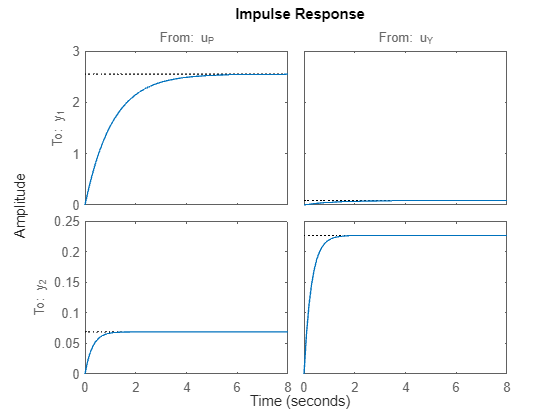

% Risposta all'impulso in anello aperto
impulse(sys);

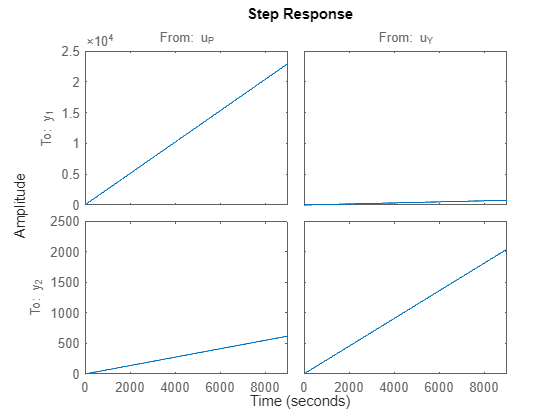


% Risposta al gradino in anello aperto
step(sys);

La risposta all'impulso in anello aperto presenta un andamento limitato ma che non converge a zero. L'assestamento è rapido nel caso degli ultimi due plot (in circa 2 secondi) e più lento nel caso dei primi due plot (in circa 5 secondi). La risposta al gradino in anello aperto presenta invece un andamento divergente a rampa.

Mi aspetto che il sistema abbia almeno un polo nell'origine dato il comportamento limitato, e non convergente a zero, nel caso della risposta all'impulso ed il comportamento divergente, e non limitato, nel caso della risposta al gradino unitario.

% Autovalori della matrice di stato
eigenvalues = eig(A)

eigenvalues =          0
         0
   -0.9260
   -3.4872


## Controllo del sistema

Una volta implementato il sistema da controllare, è necessario definire il controllore MPC. È noto che entrambi i sensori inerziali (che permettono di monitorare l'angolazione dell'elicottero ed i driver che pilotano i motori) operano ad una frequenza massima di 10 Hz.

Come ulteriore vincolo di progetto, viene richiesto di assicurare un tempo di assestamento di 0.8 secondi. 

### Scelta del periodo di campionamento

Usualmente si desidera un periodo di campionamento che sia compreso tra il 10% ed il 25% del tempo di assestamento.

Entrambi i sensori operano ad una frequenza massima di 10 Hz, dunque il periodo di campionamento è limitato a questo valore.

% Periodo di campionamento [s]
Ts = 0.1;

### Scelta dell'orizzonte di predizione

Noti il periodo di campionamento ed il tempo di assestamento, un valore per l'orizzonte di predizione può essere ottenuto dalla relazione:


$$t_s \approx T_s \cdot H_p \;\;\;\Rightarrow \;\;H_p =\frac{t_s }{T_s }=\frac{0\ldotp 8}{0\ldotp 1}=8$$


% Orizzonte di predizione
Hp = 8;

### Scelta dell'orizzonte di controllo

L'orizzonte di controllo deve essere molto più piccolo dell'orizzonte di predizione, per esempio è possibile sceglierlo uguale a 2.

% Orizzonte di controllo
Hc = 2;

### Definizione del controllore

% Controllore MPC
mpcobj = mpc(sys,Ts);

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


Una caratteristica dell'oggetto rappresentante il controllore è la possibile specificare separatamente le sue proprietà:

% Orizzonte di predizione del controllore MPC
mpcobj.PredictionHorizon = Hp;

% Orizzonte di controllo del controllore MPC
mpcobj.ControlHorizon = Hc;

Si supponga di voler controllare l'elicottero in modo che il pitch angle sia 0 ed il yaw angle sia 1.

% Riferimento
yref = [0, 1];

### Simulazione del controllo

Per verificare il corretto funzionamento del controllo, si esegue una simulazione di 10 secondi.

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #2.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


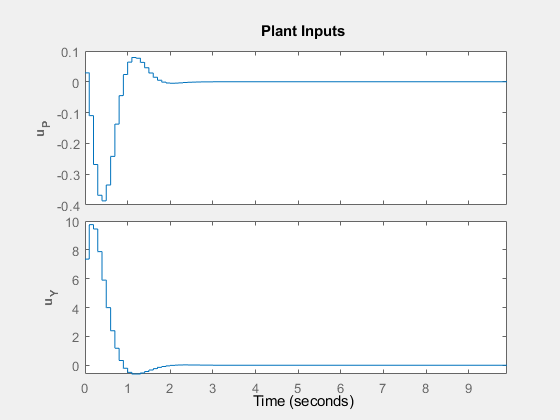

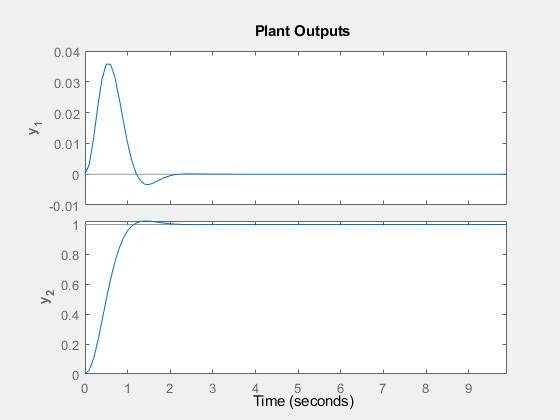

% Simulazione del controllo
sim(mpcobj, 100, yref);

La simulazione può essere alternativamente eseguita come segue.

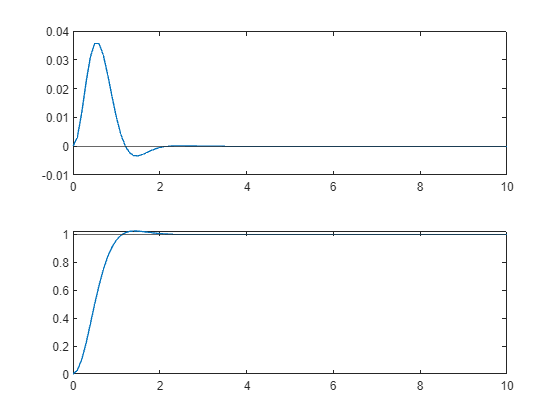

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Numero di step della simulazione
N = length(t);

% Inizializzazione delle uscite
y = zeros(N,2);

% Inizializzazione degli ingressi
u = zeros(N,2);

% Stato del sistema
xk = mpcstate(mpcobj);

% Ciclo di simulazione
for i=1:N
    y(i,:) = C*xk.Plant;
    u(i,:) = mpcmove(mpcobj,xk,y(i,:),yref);
end

% Evoluzione degli ingressi
figure(1)
subplot(2,1,1)
stairs(t, u(:,1))
subplot(2,1,2)
stairs(t, u(:,2))

% Evoluzione delle uscite
figure(2)
subplot(2,1,1)
plot(t, y(:,1))
yline(yref(1));
subplot(2,1,2)
plot(t, y(:,2))
yline(yref(2));

### Analisi dei risultati

La simulazione dimostra come, in circa 2 secondi, il controllore sia in grado di stabilizzare le uscite ai valori desiderati. Il picco iniziale della prima uscita può non sembrare particolarmente incoraggiante, tuttavia occorre osservarne l'entità: appena 0.04 radianti (2.3 gradi).

## Vincoli del sistema

A seguito della lettura del datasheet dei motori ci si è accorti che la massima tensione supportata in ingresso è, in valore assoluto, di 12 V. Nel datasheet viene inoltre consigliato di evitare picchi di corrente durante la partenza e la frenata, e di controllare i motori usando rampe di accelerazione e di decelerazione. Il minimo tempo di salita e di discesa richiesto dalle rampe per passare da 0 V a 12 V è di 4 secondi.

### Definizione di un vincolo sugli ingressi

Dalle precedenti simulazioni, sembra che il vincolo sulla massima tensione supportata in ingresso sia già soddisfatto. Tuttavia, per sicurezza, occorre modificare il controllore MPC andando a specificare il minimo e massimo valore che possono assumere gli input.

% Vincolo sul valore minimo degli ingressi
mpcobj.ManipulatedVariables(1).Min = -12;
mpcobj.ManipulatedVariables(2).Min = -12;

% Vincolo sul valore massimo degli ingressi
mpcobj.ManipulatedVariables(1).Max = 12;
mpcobj.ManipulatedVariables(2).Max = 12;

Eseguendo nuovamente la simulazione, come previsto, il vincolo sugli ingressi non ha alcun effetto perché già limitati nell'intervallo desiderato.

% Simulazione del controllo
sim(mpcobj, 100, yref);

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #2.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


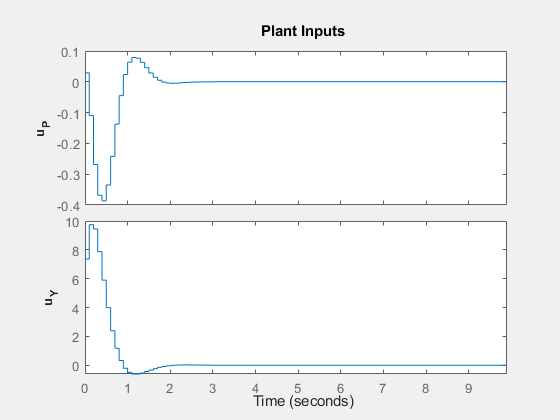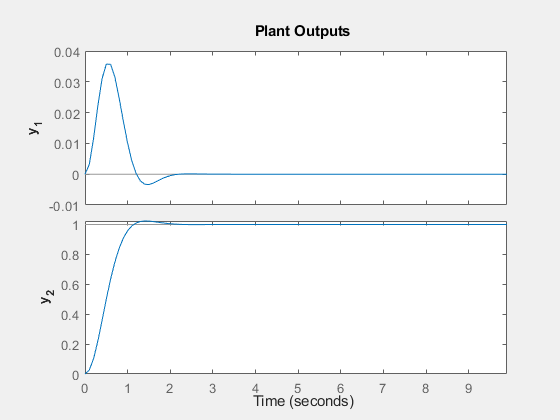

### Definizione di un vincolo sulla variazione degli ingressi

Per fare in modo che non vi siano picchi di corrente in fase di partenza e di frenata, si può pensare di imporre un vincolo sulla variazione delle tensioni in ingresso. Occorre modificare il controllore MPC andando a specificare il valore minimo e massimo che possono assumere i rate.

% Vincolo sul valore minimo del rate
mpcobj.ManipulatedVariables(1).RateMin = -0.3;
mpcobj.ManipulatedVariables(2).RateMin = -0.3;

% Vincolo sul valore massimo del rate
mpcobj.ManipulatedVariables(1).RateMax = 0.3;
mpcobj.ManipulatedVariables(2).RateMax = 0.3;

Eseguendo nuovamente la simulazione, è possibile apprezzare il soddisfacimento del vincolo sui rate.

% Simulazione del controllo
sim(mpcobj, 100, yref);

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #2.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


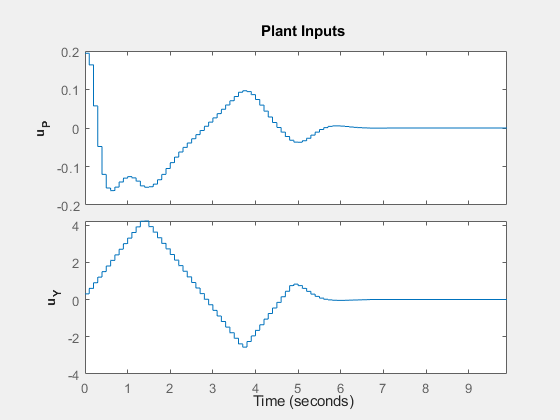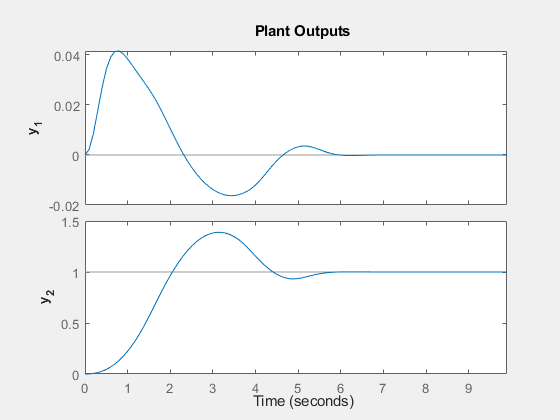

Le limitazioni imposte dal vincolo sui rate comportano la comparsa di oscillazioni più importanti nelle uscite.

### Tuning dell'orizzonte di predizione

Si può pensare di andare ad agire sull'orizzonte di predizione per andare a compensare le oscillazioni nelle uscite.

% Modifica dell'orizzonte di predizione
mpcobj.PredictionHorizon = Hp + 5;

Eseguendo nuovamente la simulazione, è possibile apprezzare un netto miglioramento sugli andamenti delle uscite.

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #2.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


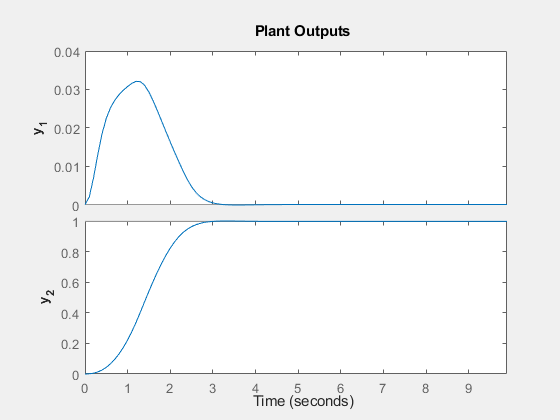

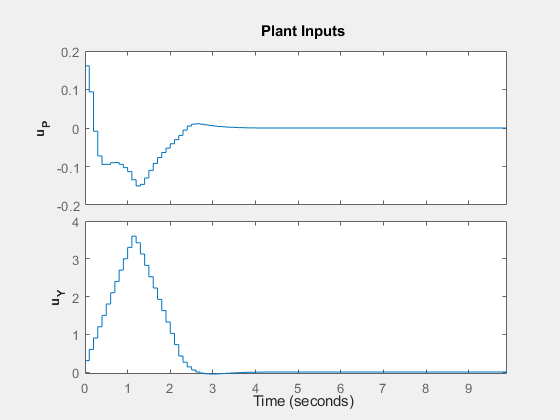

% Simulazione del controllo
sim(mpcobj, 100, yref);

Avendo aumentato l'orizzonte di predizione, vengono compensate le oscillazioni nella prima uscita e l'overshoot nella seconda uscita.

### Definizione di un vincolo dinamico sul riferimento

Viene richiesto di impostare, dopo 5 secondi, il pitch angle a 25 gradi. Si può pensare di imporre il vincolo andando ad agire direttamente sul ciclo di simulazione. A tal proposito, poiché si deve eseguire un controllo sull'istante di tempo, è necessario cambiare la struttura del ciclo.

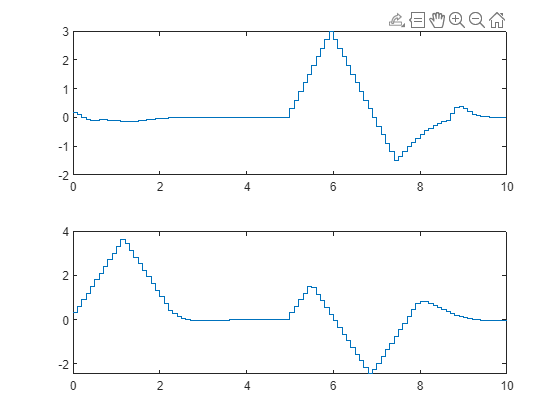

% Inizializzazione del vettore di uscita
y_history = [];

% Inizializzazione del vettore di ingresso
u_history = [];

% Inizializzazione del vettore di riferimento
r_history = [];

% Stato del sistema
xk = mpcstate(mpcobj);

% Ciclo di simulazione
for i=0:Ts:Tf
    if (i==5)
        yref = [5 1];
    end
    yk = C*xk.Plant;
    uk = mpcmove(mpcobj,xk,yk,yref);
    u_history = [u_history; uk'];
    y_history = [y_history; yk'];
    r_history = [r_history; yref];
end

% Evoluzione degli ingressi
figure(1)
subplot(2,1,1)
stairs(t,u_history(:,1))
subplot(2,1,2)
stairs(t,u_history(:,2))


% Evoluzione delle uscite
figure(2)
subplot(2,1,1)
plot(t,y_history(:,1))
hold on
plot(t,r_history(:,1))
subplot(2,1,2)
plot(t,y_history(:,2))
hold on
plot(t,r_history(:,2))

L'imposizione del vincolo dinamico sul riferimento comporta, evidentemente, la comparsa di picchi contenuti in entrambe le uscite.